# Getting Started with M-M.E.S.S.

## Description

The M-M.E.S.S. toolbox provides solvers for  large-scale, sparse, symmetric linear and quadratic matrix equations. These can be algebraic and differential equations and the solvers are in their core all based on the low-rank ADI method.  M-M.E.S.S. can be seen as the successor to the LyaPack toolbox with an improved formulation of the ADI, that now properly supports generalized state space systems, but also special structured DAEs. It features additional solvers for differential equations, improved shift parameter computation and a guarantee to compute real low-rank factorizations, but follows the same general philosophy of user supplied functions that the LyaPack toolbox used.

## System Requirements

Runs on MATLAB R2014b and later. For some solvers the availablility of the Control System Toolbox is beneficial.

## Features

- large-scale algebraic Lyapunov equations (mess_lyap, mess_lradi)

- large-scale algebraic Riccati equations (mess_care, mess_lrnm, mess_lrri, mess_lrradi)

- large-scale differential Riccati equations (mess_bdf_dre, mess_rosenbrock_dre, mess_splitting_dre)

- model order reduction (mess_balanced_truncation, mess_square_root_method, mess_tangential_IRKA)

All of them for standard state space systems, second order systems and differential algebraic equation systems allowing implicit index-reduction. 

## M-M.E.S.S. philosophy and equation structures

To learn the basics about the philosophy behind the implementation of our solvers and the exact representation of the matrix equations check:

help mess

   ######################################################################
   #                                                                    #
   #          M-M.E.S.S. - Matrix Equations, Sparse Solvers             #
   #                                                                    #
   ######################################################################
 
   version 2.0.0
  
   The M-M.E.S.S. toolbox is intended for the solution of symmetric
   linear and quadratic, differential and algebraic matrix
   equations with real, large, and sparse (or sparse + low-rank)
   coefficient matrices in the linear terms, low-rank quadratic and
   constant terms, and low-rank solutions.  
  
   Using the user supplied functions (usfs) framework,
   M-M.E.S.S. enables the solution of equations for several
   system structures. While implicitly M-M.E.S.S. always treats a
   system 
       . 
     E x(t) = A x(t) + B u(t),                                 (1)
       y(t) = C x(t),
 
   with

## Examples

We first load the Oberwolfach Rail example ([https://morwiki.mpi-magdeburg.mpg.de/morwiki/index.php/Steel_Profile](https://morwiki.mpi-magdeburg.mpg.de/morwiki/index.php/Steel_Profile)) 

eqn = getrail(1); %change the number between 0 and 5 to get other sizes
E = eqn.E_;
A = eqn.A_; 
B = eqn.B; 
C = eqn.C;

## **Solutions to Lyapunov and Riccati equations**

For a simple standard (E, A, B, C) input output system with sparse E, A and thin rectangular B and C like the rail, simply call :

Zl = mess_lyap(A,B,[],[],E);

to compute, e.g., a controlability Gramian factor Zl. 

Similarly, 

[Zr, K] = mess_care(A, B, C, [], E);

can be used to compute a low-rank factor  Zr for the stabilizing solution of the linear quadratic regulator problems algebraic Riccati equation and the corresponding feedback gain matrix K. 

For structured problems and to take control of the soultion process via the many process parameters, one needs to run one of the low level solvers listed in the 'Features' section above. Check the DEMOS folder for various examples and consult the help texts of the single methods for the available parameters. 

## Model Order Reduction

To reduce the above model by Balanced truncation to at most order 15 with a desired error of 1e-5 use:

    -1.704875289214444e-01
    -1.160889244984667e-01
    -8.464685068930794e-02
    -3.977240106081215e-02
    -3.123765604395698e-02
    -2.905113801049488e-02

ADI Shifts:
    -1.704875289214444e-01
    -1.160889244984667e-01
    -8.464685068930794e-02
    -3.977240106081215e-02
    -3.123765604395698e-02
    -2.905113801049488e-02

ADI step:    1 normalized residual: 6.339052e-01 relative change in Z: 1.000000e+00
ADI step:    2 normalized residual: 4.528296e-01 relative change in Z: 4.970393e-01
ADI step:    3 normalized residual: 3.839213e-01 relative change in Z: 4.359048e-01
ADI step:    4 normalized residual: 2.945325e-01 relative change in Z: 4.279526e-01
ADI step:    5 normalized residual: 2.488714e-01 relative change in Z: 3.775197e-01
ADI step:    6 normalized residual: 2.147136e-01 relative change in Z: 3.154944e-01
updating shifts
    -1.151892757974292e-02
    -1.241939791873257e+00
    -1.725257816523001e-04
    -1.147176245719061e-01
    -1.287991482155716e-03
    -3.

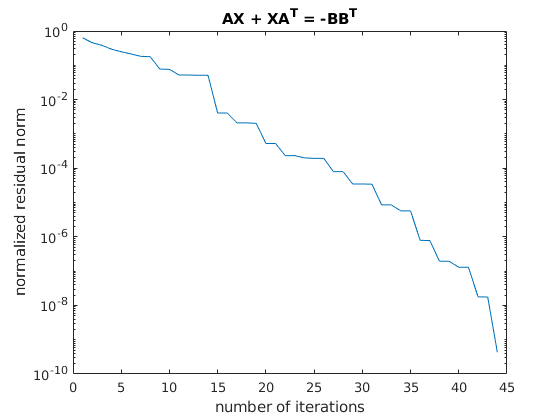

size outB.Z:


ans =         1357         308


ADI Shifts:
    -1.704875289214444e-01
    -1.160889244984667e-01
    -8.464685068930794e-02
    -3.977240106081215e-02
    -3.123765604395698e-02
    -2.905113801049488e-02

ADI step:    1 normalized residual: 2.740713e-01 relative change in Z: 1.000000e+00
ADI step:    2 normalized residual: 1.461377e-01 relative change in Z: 4.541159e-01
ADI step:    3 normalized residual: 8.364776e-02 relative change in Z: 2.992036e-01
ADI step:    4 normalized residual: 4.675013e-02 relative change in Z: 2.788981e-01
ADI step:    5 normalized residual: 2.530137e-02 relative change in Z: 2.057674e-01
ADI step:    6 normalized residual: 1.925511e-02 relative change in Z: 1.603543e-01
updating shifts
    -4.323846034559988e-02
    -8.997873971813871e-01
    -2.132410172054207e-03
    -2.086550318725701e-01
    -1.012834315760541e-02
    -4.337144530816658e-03

ADI step:    7 normalized residual: 1.399040e-02 relative change in Z: 1.100694e-01
ADI step:    8 normalized residual: 9.032480e-03 relative 

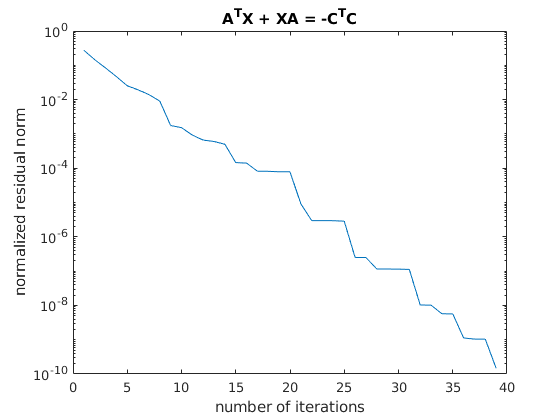

size outC.Z:


ans =         1357         234


reduced system order: 15  (max possible/allowed: 234/15)

Computing TFMs of original and reduced order systems and MOR errors

 Step  10 / 100
 Step  20 / 100
 Step  30 / 100
 Step  40 / 100
 Step  50 / 100
 Step  60 / 100
 Step  70 / 100
 Step  80 / 100
 Step  90 / 100
 Step 100 / 100



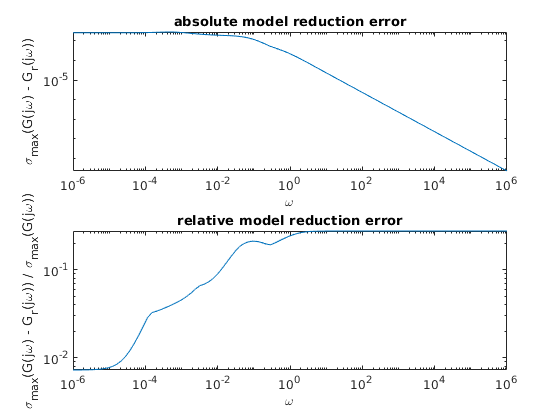

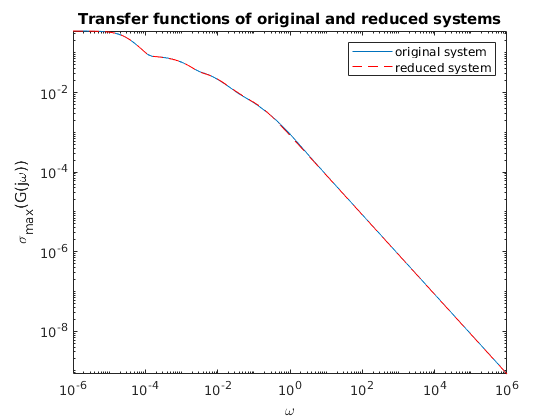

[Abt, Bbt, Cbt] = mess_balanced_truncation(E,A,B,C,15,1e-5,3);

Note that our implementation will always compute a standard state space model with Er being the identity. Analogously, for a tangential IRKA approximation of order 15, with logspaced initial shifts, call:

IRKA step   1, rel. chg. shifts = 1.729502e+01 , rel. H2-norm chg. ROM = 1.000000e+00


IRKA step   2, rel. chg. shifts = 5.091970e+00 , rel. H2-norm chg. ROM = Inf
IRKA step   3, rel. chg. shifts = 2.257340e+00 , rel. H2-norm chg. ROM = 9.971688e-01


IRKA step   4, rel. chg. shifts = 1.430068e+00 , rel. H2-norm chg. ROM = Inf


IRKA step   5, rel. chg. shifts = 1.699172e+01 , rel. H2-norm chg. ROM = Inf
IRKA step   6, rel. chg. shifts = 1.726086e+01 , rel. H2-norm chg. ROM = 5.452293e+00
IRKA step   7, rel. chg. shifts = 8.785465e-01 , rel. H2-norm chg. ROM = 2.150031e-01
IRKA step   8, rel. chg. shifts = 1.697579e+00 , rel. H2-norm chg. ROM = 1.011335e-01
IRKA step   9, rel. chg. shifts = 1.810172e-01 , rel. H2-norm chg. ROM = 5.423849e-02
IRKA step  10, rel. chg. shifts = 5.129312e-01 , rel. H2-norm chg. ROM = 4.205981e-02
IRKA step  11, rel. chg. shifts = 3.321396e-01 , rel. H2-norm chg. ROM = 2.808732e-02
IRKA step  12, rel. chg. shifts = 4.314060e-02 , rel. H2-norm chg. ROM = 1.658318e-02
IRKA step  13, rel. chg. shifts = 1.775376e-02 , rel. H2-norm chg. ROM = 1.257415e-02
IRKA step  14, rel. chg. shifts = 1.793331e-02 , rel. H2-norm chg. ROM = 1.400940e-02
IRKA step  15, rel. chg. shifts = 1.489473e-02 , rel. H2-norm chg. ROM = 1.826396e-02
IRKA step  16, rel. chg. shifts = 1.233509e-02 , rel. H2-norm c

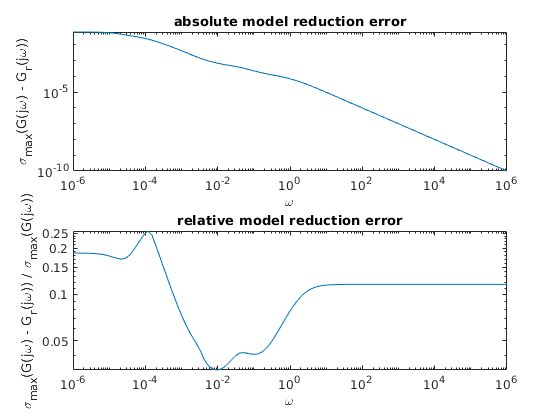

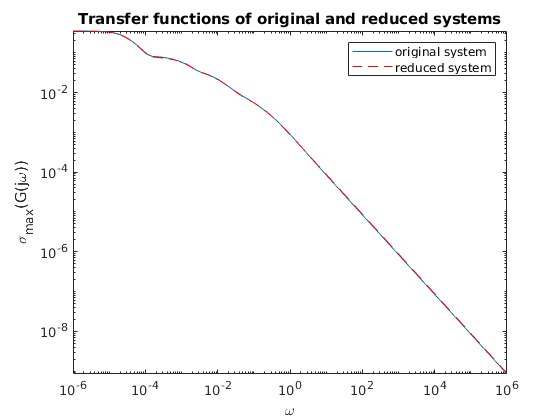

opts.irka.r = 15;
opts.irka.info = 2;

opts.irka.init = 'logspace';

[Ei, Ai, Bi, Ci] = mess_tangential_irka(E,A,B,C,opts);

Again many more model order reduction examples can be found in the DEMOS folder. 